# **2024  OFDM Encoder for 6G**

% Code by: Sheng-Yuan (Shawn)Zheng
% Refer to Yu-Chang Chen code, coperate with Zheng Wei
% This code address the previous code SNR issue!

## --- Preset ---

close all; clear all; clc;

figON = 1; % Set 1 to display all figures
LPF = 1; % Set 1 to use Low pass filter
load("TestingBERSNR.mat"); % Using in testing SNR
disp('--- Execute encoding ---')

--- Execute encoding ---


## --- Parameter Setup ---

ModLv = 2;
SigBW = 5e9; % 6G: 5GHz (Max:11.8 GHz), 5G: 3G BW
FFTsize = 512;
Nsc = 400; % Nsc <= FFTsize
FFTBW = SigBW* (FFTsize/Nsc);
CPratio = 1/8; % modify by yourself
FsDAC = 50e9; % Sampling rate for DAC
FsADC = 80e9; % Sampling rate for ADC
RefLen = 5000; % Reference Length for synchronization and ZF
F_IF = 3.5e9;
Trainning_ratio = 0.1

Trainning_ratio = 0.1000

PayLoadLen = 60

PayLoadLen = 60

% floor (((1024*180*2) /FFTsize) / (FsDAC / SigBW)* (1 - CPratio) / (1 + Training_ratio))
% Symbol Length = floor ((The biggest point that scope can accept) /FFTsize) 
% / (FsDAC / SigBW)* (1 - CPratio) / (1 + Training_ratio))
delta_f = FFTBW/FFTsize;
Training_Length = round(PayLoadLen* Trainning_ratio);

## --- Display Bandwidth ---

disp(['Original Signal Bandwidth = ' num2str(FFTBW / 1e9) 'GHz']);

Original Signal Bandwidth = 6.4GHz


disp(['Effective Signal Bandwidth = ' num2str(FFTBW/(FFTsize/Nsc)/1e9) 'GHz']);

Effective Signal Bandwidth = 5GHz


disp(['delta f = ' num2str((FFTBW/FFTsize)/10^6) 'MHz']);

delta f = 12.5MHz


disp(['Nsc = ' num2str(Nsc)]);

Nsc = 400


## --- Data Generation ---

tx1 = randi([0 1], 1, Nsc* PayLoadLen* ModLv);
% tx1_training = randi([0 1], 1, Nsc* Training_Length* ModLv);
SymLen = PayLoadLen;

## --- S/P Conversion ---

tx2 = reshape(tx1, Nsc, []);    % Serial to parallel
% tx2_training = reshape(tx1_training, Nsc, []);

## --- Symbol mapper ---

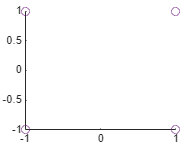

tx3 = modulation(tx2, ModLv, Nsc, SymLen);  % QAM mapper
% tx3_training = modulation(tx2_training, ModLv, Nsc, Training_Length);
% fileName1 = ['Tx_' num2str(2^ModLv) 'QAM_Constellation_R'];
% fileName2 = ['Tx_' num2str(2^ModLv) 'QAM_Constellation_I'];
% xlswrite(fileName1, real(tx3));
% xlswrite(fileName2, imag(tx3));
scatter(real(tx3),imag(tx3));

## --- Interleave Symbol (Time Domain Trainning) ---

% tx3 = [];
% interleaveLen = round(PayLoadLen / Training_Length);
% for interleaveIndex = 1 : Training_Length
%     tx3 = [tx3 tx3_training(:, interleaveIndex)];
%     tx3 = [tx3 tx3_payLoad(:, (interleaveIndex - 1)* interleaveLen + 1 : interleaveIndex* interleaveLen)];
% end
% tx3 = [tx3 tx3_payLoad(:, 61)];
% training(:, 1) cascade payload(:, 1:10) So on and so forth

## --- Zero Padding ---

tx4 = zeropad(tx3, Nsc, FFTsize, SymLen);   % Zero-pad unused subcarrie

## --- IFFT ---

%% Discrete Time Signal
tx5 = ifft(tx4);
%% Rayleigh Fading channel
% tx4_ray = tx4.*H;
% tx5 = ifft(tx4_ray)

## --- CP Insertion(Guard Interval Insertion) ---

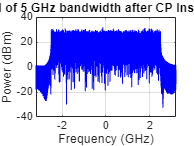

tx6 = GIIns(tx5, FFTsize, CPratio, SymLen); % The signal after CP Insertion

if figON == 1
    figure('Name', 'Baseband OFDM');
    spectraplot(tx6, 'b', FFTBW);
    str = sprintf('Baseband OFDM of %d GHz bandwidth after CP Insertion (GI Insertion)', SigBW / 1e9);
    title(str);
    grid on;
end

## --- Resample ---

% normalizeBW = SigBW/FsDAC+2e-3;
% b = firls(301,[0 normalizeBW normalizeBW+1e-4 1],[1 1 0 0]);
% tx6 = resample(tx6, FsDAC, SigBW, b);   % Resample (SigBW -> FsDAC)
tx7 = resample(tx6, FsDAC, FFTBW);


## --- Up Conversion ---

%% tx7 is C.T. signal
tstpDAC = 1 / FsDAC;    % Sampling period
timeWin = length(tx7) * tstpDAC;    % Time window for up conversion
tt = 0 : tstpDAC : timeWin - tstpDAC;   % Time grid(i.e. time axis)

tx8i = real(tx7) .* cos(2 * pi * F_IF * tt);    % Up conversion the real part to intermediate frequency.
tx8q = imag(tx7) .* sin(2 * pi * F_IF * tt);    % Up conversion the imaginary part to intermediate frequency
tx8 = tx8i - tx8q;


## --- Signal Output ---

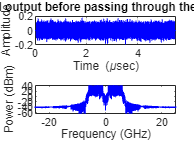

%% For experiment mode
tx9 = [zeros(1, round(RefLen / 2)), tx8, zeros(1, round(RefLen /2))];   % The zeros is used to synchronize the signal.
signalOutput = fopen(['Input', '.txt'], 'w');
fprintf(signalOutput, '%f \n', tx9);
fclose(signalOutput);

filename = [num2str(2 ^ ModLv) 'QAM_IF ' ...
            num2str(F_IF / 1e9) 'GHz_BW ' ...
            num2str(SigBW / 1e9) 'GHz'];
signalOutput = fopen(['Sig_' filename '.txt'], 'w');
fprintf(signalOutput, '%f \n', tx9);
fclose(signalOutput);

if figON == 1
    figure('Name', 'Output OFDM');
    subplot(2, 1, 1);
    waveplot(tx9, 'b', FsDAC);
    title('signal output before passing through the channel');
    grid on;
    subplot(2, 1, 2);
    spectraplot(tx9, 'b', FsDAC);
end

## --- AWGN Channel ---

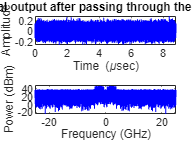

%% AWGN channel
SNRdB = 10;
% SNRdB = SNRIndex; % Using in test different SNR
tx10 = resample(tx9, FsADC, FsDAC);      % Resample (FsDAC -> FsADC)
SNRch = SNRdB - 10* log10(FsDAC / FFTBW) - 10* log10(FsADC / FsDAC);
rx1_simu = awgn(tx10, SNRch, 'measured');

% [Wei] The original code needs to resample to 16 GHz. Due 
% to the filter in the 'resample' function, the noise in the bandwidth 
% greater than FsADC is eliminated.
% I modified the SNR value in the AWGN function so that it can approximate 
% the SNR at the receiver for "HIGH" SNR.

if figON == 1
    figure('Name','after Channel'),
    subplot(2,1,1),waveplot(rx1_simu,'b', FsDAC)
    title('signal output after passing through the channel'),grid on
    subplot(2,1,2),spectraplot(rx1_simu, 'b',FsDAC)
end

## --- Decoder Reference ---


if LPF == 1
    LPFDesign = designfilt('lowpassfir', ...
        'PassbandFrequency', SigBW * 0.5, ...
        'StopbandFrequency', SigBW * 0.545, ...
        'PassbandRipple', 0.01, ...
        'StopbandAttenuation', 200, ...
        'Sample', FsDAC);
    % if figON ==1
    %     fvtool(LPFDesign);  % Plot LPF response
    % end
    save(['LPF design for_' filename '.mat'], 'LPFDesign');
end
save(['Param_' filename '.mat'], ...
    'SigBW','FFTBW', 'ModLv', 'Nsc', ...
    'PayLoadLen', 'SymLen', 'Training_Length', ...
    'FFTsize', 'CPratio', 'Trainning_ratio', ...
    'FsDAC', 'FsADC', 'RefLen', 'delta_f');
save(['Ref_' filename '.mat'], ...
    'tx1', 'tx3', 'tx7', 'tx8', 'tx10', 'rx1_simu');


% --- EOF ---